%Ejemplo Estimador de media muestral con mínimos cuadrados
A=3.5; % valor DC de la señal xn "desconocido"
num=50

num = 50

dAh=zeros(1,num-1)

dAh =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


vAh=zeros(1,num-1)

vAh =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k=1

k = 1

while k<num
N=1000; % número de muestras de xn
xn=A+3*normrnd(0,1,N,1); % señal con ruido Gaussiano (media=0, sigma=1)
%Optimización por gradiente descendente
% punto de partida
A_h=xn(1);
%parametros de optimizacion
stop = 1;
step=0.1;
max_iter=500;
iter=0;
% loop de optimización
while stop > 0.00001 && iter<max_iter
    A_hp=A_h;
    err=-sum((xn-A_h))/N;
    A_h=A_h-step*err;
    stop = abs(A_h-A_hp);
    iter = iter+1;
end
%Resultado final
A_h
error = abs(A-A_h)
dAh(1,k)=A_h
k=k+1
end

A_h = 3.4693

error = 0.0307

dAh =     3.4693         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 2

A_h = 3.3533

error = 0.1467

dAh =     3.4693    3.3533         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 3

A_h = 3.5487

error = 0.0487

dAh =     3.4693    3.3533    3.5487         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 4

A_h = 3.3711

error = 0.1289

dAh =     3.4693    3.3533    3.5487    3.3711         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 5

A_h = 3.6167

error = 0.1167

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 6

A_h = 3.5154

error = 0.0154

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 7

A_h = 3.4728

error = 0.0272

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 8

A_h = 3.4578

error = 0.0422

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 9

A_h = 3.5476

error = 0.0476

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 10

A_h = 3.4623

error = 0.0377

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 11

A_h = 3.5274

error = 0.0274

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 12

A_h = 3.5664

error = 0.0664

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 13

A_h = 3.6484

error = 0.1484

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 14

A_h = 3.4749

error = 0.0251

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 15

A_h = 3.6150

error = 0.1150

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 16

A_h = 3.4415

error = 0.0585

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 17

A_h = 3.4950

error = 0.0050

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 18

A_h = 3.6087

error = 0.1087

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 19

A_h = 3.5021

error = 0.0021

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 20

A_h = 3.4946

error = 0.0054

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 21

A_h = 3.4644

error = 0.0356

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 22

A_h = 3.4687

error = 0.0313

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 23

A_h = 3.6320

error = 0.1320

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 24

A_h = 3.5105

error = 0.0105

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 25

A_h = 3.3881

error = 0.1119

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 26

A_h = 3.3791

error = 0.1209

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 27

A_h = 3.4248

error = 0.0752

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 28

A_h = 3.6521

error = 0.1521

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 29

A_h = 3.2619

error = 0.2381

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 30

A_h = 3.6012

error = 0.1012

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 31

A_h = 3.3575

error = 0.1425

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 32

A_h = 3.3217

error = 0.1783

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 33

A_h = 3.5762

error = 0.0762

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 34

A_h = 3.6122

error = 0.1122

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 35

A_h = 3.5514

error = 0.0514

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 36

A_h = 3.4525

error = 0.0475

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525         0         0         0         0         0         0         0         0         0         0         0         0         0


k = 37

A_h = 3.3753

error = 0.1247

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753         0         0         0         0         0         0         0         0         0         0         0         0


k = 38

A_h = 3.4668

error = 0.0332

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668         0         0         0         0         0         0         0         0         0         0         0


k = 39

A_h = 3.5056

error = 0.0056

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056         0         0         0         0         0         0         0         0         0         0


k = 40

A_h = 3.4360

error = 0.0640

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360         0         0         0         0         0         0         0         0         0


k = 41

A_h = 3.4083

error = 0.0917

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083         0         0         0         0         0         0         0         0


k = 42

A_h = 3.5455

error = 0.0455

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455         0         0         0         0         0         0         0


k = 43

A_h = 3.5225

error = 0.0225

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225         0         0         0         0         0         0


k = 44

A_h = 3.5927

error = 0.0927

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225    3.5927         0         0         0         0         0


k = 45

A_h = 3.5113

error = 0.0113

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225    3.5927    3.5113         0         0         0         0


k = 46

A_h = 3.4082

error = 0.0918

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225    3.5927    3.5113    3.4082         0         0         0


k = 47

A_h = 3.4978

error = 0.0022

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225    3.5927    3.5113    3.4082    3.4978         0         0


k = 48

A_h = 3.5523

error = 0.0523

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225    3.5927    3.5113    3.4082    3.4978    3.5523         0


k = 49

A_h = 3.5998

error = 0.0998

dAh =     3.4693    3.3533    3.5487    3.3711    3.6167    3.5154    3.4728    3.4578    3.5476    3.4623    3.5274    3.5664    3.6484    3.4749    3.6150    3.4415    3.4950    3.6087    3.5021    3.4946    3.4644    3.4687    3.6320    3.5105    3.3881    3.3791    3.4248    3.6521    3.2619    3.6012    3.3575    3.3217    3.5762    3.6122    3.5514    3.4525    3.3753    3.4668    3.5056    3.4360    3.4083    3.5455    3.5225    3.5927    3.5113    3.4082    3.4978    3.5523    3.5998


k = 50

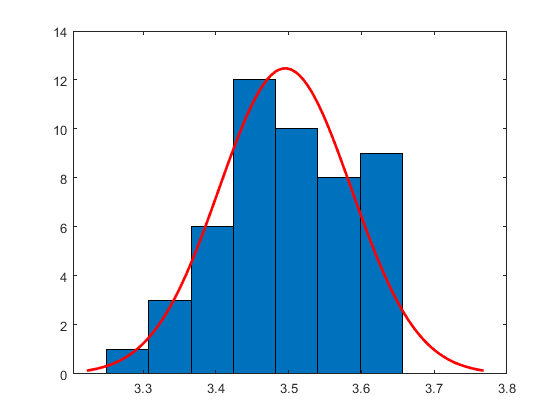

histfit(dAh)

media=mean(dAh)

media = 3.4952

Varianza=var(dAh)

Varianza = 0.0083